clear all

# Exercise 3.3 - Velocity Teleoperation

In this exercise you will write a code to teleoperate a universal robot of your choice. 

When using a teleoperation interface, you will use your keyboard to control a simulated robot. 

## Task: 

Write a code that maps the desired cartesian velocity to the joint space and sends the joint speeds to the simulation environment. The cartesian velocity to be controlled is either w.r.t. the Base frame or the End-Effector frame. 

## Tools: 

You can use predefined functions to retrieve information from the simulation environment. 

- GetJointStates() returns a vector containing the current configuration as $\vec{q} \in {\mathbb{R}}^{6\textrm{x1}}$

- GetTeleoperation() returns a vector containing the cartesian velocity as $\vec{v} =\left\lbrack \begin{array}{c}
\dot{x} \\
\dot{y} \\
\dot{z} \\
\omega_x \\
\omega_y \\
\omega_z 
\end{array}\right\rbrack$ and 

               a string containing the current reference frame as $\textrm{Mode}\in \left\lbrack \textrm{"Base"},\textrm{"EndEffector"}\right\rbrack$

- SendJointSpeeds(q_dot) will publish the computed joint velocities to the simulation environment

## Implementation Tips: 

You may choose to model the robot using the Robotic System Toolbox or the Symbolic Toolbox. 

Use the function waitfor(time) to implement a delay between broadcasting, start with a frequency of 50 Hz. 

#### Hints: 

- Remember that the Robotic System Toolbox returns the Jacobian as $J=\left\lbrack \begin{array}{c}
J_{\Theta \;} \\
J_p 
\end{array}\right\rbrack$

- If norm(q_dot) > 1 you should normalize the velocities as $q_{\textrm{dot},\textrm{norm}} =\frac{q_{\textrm{dot}} }{\textrm{norm}\left(q_{\textrm{dot}} \right)}$

- Plot the manipulability ellipsoid by calling JointStatesToRviz(q, ur_model, [ ], 'Ellipsoid', true);

## Teleoperation Interface

The teleoperation program gives the following input options: 

Desired Velocity (linear or angular) controller by keys W-A-S-D-SPACE-CTRL, see the terminal for more information)

- W for ${\dot{x} }^+ \;\textrm{or}\;\omega_x^+$

- S for ${\dot{x} }^- \;\textrm{or}\;\omega_x^-$

- D for ${\dot{y} }^+ \;\textrm{or}\;\omega_y^+$

- A for ${\dot{y} }^- \;\textrm{or}\;\omega_y^-$

- SPACE for ${\dot{z} }^+ \;\textrm{or}\;\omega_z^+$

- CTRL (Control) for  ${\dot{z} }^- \;\textrm{or}\;\omega_z^-$

You can toggle between angular or linear velocity by pressing: 

- TAB 

You can toggle the reference frame from "Base" to "EndEffector" by pressing: 

- M

You can double the speed command by holding: 

- SHIFT

To stop the programm press q or ESC. You don't need to write in the terminal, it will recognize all keystrokes outside of the programm (including q and ESC!)

You can see the controls in the terminal: 

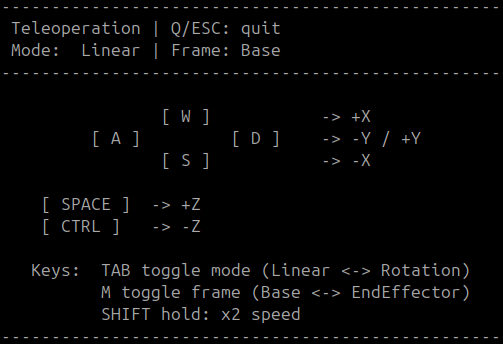

## Start Applications: 

To start the required programms and simulations execute (once): 

StartTutorialApplication('Simulation', 'Controller','Speed'); 
StartTutorialApplication('Teleoperation');

If you run this on a native ubuntu system (no docker): 

% StartTutorialApplication('Simulation', 'Controller', 'Speed', 'Docker',false); 
% StartTutorialApplication('Teleoperation', 'Docker', false);

To see the path of the end effector you can run: 

StartTutorialApplication('Trajectory'); 
% If you use ROS on a native Ubuntu system use: 
% 


## Code here: 

*You must run this code after starting the required programs and simulations to be able to control the robot properly with the keyboard.*

model = "universalUR5e";

robot = loadrobot(model, DataFormat="column"); 

freq = 50; 

while true
    try
        current_q = GetJointStates(); 
        JointStatesToRviz(current_q, model, [ ], 'Ellipsoid', true, 'EllipsoidResolution', 15, 'SendJointStates', false);
    
        J = geometricJacobian(robot, current_q, "tool0"); 
        J = [J(4:6,:);J(1:3,:)];
    
        [desiredVelocity, WorkMode] = GetTeleoperation(); 
    
        if strcmp(WorkMode, "Base")
            q_dot = pinv(J) * desiredVelocity; 
        else
            T06 = getTransform(robot, current_q, 'tool0'); 
            R06 = T06(1:3,1:3); 
            J_EE = [R06'*J(1:3,:); R06'*J(4:6,:)];
            q_dot = pinv(J_EE) * desiredVelocity; 

        end

        if norm(q_dot) > 1
            q_dot = q_dot / norm(q_dot);  %normalize if module is greater than 1
        end

        SendJointSpeeds(q_dot);
    end
waitfor(1/freq); 

end